# Sinusfahrt zur Abschätzung der Kameraverzögerung

Dieses Skript dient der Ermittlung der Verzögerung der Kameradaten durch Berechnung der Roboterposition, Packen und Senden des UDP-Datenpakets.

Hierzu wird der Roboter in x-Achse mit einem Sin()-förmigen Geschwindikeitsverlauf angestuert. Die Verzögerung ermittelt sich entsprehcend aus der Pjhasendifferenz zwischen Encoderdaten und Kameradaten.

## Einlesen der Messwerte

clear all
clc, close all;
FIRST_MEASUREMENT_IDX = 366;
LAST_MEASUREMENT_IDX = 4378;

% Messwerte einlesen und Lücken in Daten durch Mittelwerte ersetzen
filename = "sinusfahrt.csv";
data = readtable(filename);

% Zeitvektor
t = table2array(data(:,"Time"));
t = t(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX)/1000;

% Encoder-Daten
vxEnc = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"vXFromMotor"));
vyEnc = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"vYFromMotor"));
omegaEnc = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"vThetaFromMotor"));

% Kameradaten
xCam = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"camX"));
thetaCam = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"camTheta"));

% Preprocessing der Kameradaten
oldTheta = 0;
for row = 1 : length(thetaCam)
    if thetaCam(row) == 0
        thetaCam(row) = oldTheta;
    else
        oldTheta = thetaCam(row);
    end
end

oldCamX = 0;
for row = 1 : length(xCam)
    if xCam(row) == 0
        xCam(row) = oldCamX;
    else 
        oldCamX = xCam(row);
    end
end



## Theta Fit

fncTheta = @(x, b) (b(1)*x + b(2));
fitTheta = @(b)(sum((fncTheta(t',b)-thetaCam').^2))

fitTheta = function_handle with value:
    @(b)(sum((fncTheta(t',b)-thetaCam').^2))


b0Theta = [1, 0];
bOptTheta = fminsearch(fitTheta, b0Theta)

bOptTheta =     0.0048   -2.9985


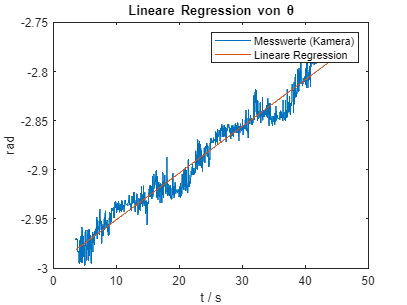


figure()
plot(t, thetaCam, t, fncTheta(t, bOptTheta));
title("Lineare Regression von \theta")
legend('Messwerte (Kamera)', 'Lineare Regression')
xlabel('t / s')
ylabel('rad')

## Transformieren der Robotergeschwindigkeiten in globale Geschwindigkeiten

vXEncGlobal = cos(fncTheta(t, bOptTheta)).*vxEnc - sin(fncTheta(t, bOptTheta)).*vyEnc;
% vXEncGlobal = cos(fncTheta(t, bOptTheta) - 0.15/16*2*pi).*vxEnc - sin(fncTheta(t, bOptTheta) - 0.15/16*2*pi).*vyEnc;
% vXEncGlobal = cos(thetaCam - 0.15/16*2*pi).*vxEnc - sin(thetaCam - 0.15/16*2*pi).*vyEnc;

## Sinus-Approximation der globalen x-Geschwindigkeit (Encodern)

fncvXEncGlobal = @(x, b) (b(1)*sin(2*pi*b(2)*x + b(3)) + b(4))

fncvXEncGlobal = function_handle with value:
    @(x,b)(b(1)*sin(2*pi*b(2)*x+b(3))+b(4))


fitvXEncGlobal = @(b)(sum((fncvXEncGlobal(t',b)-vXEncGlobal').^2))

fitvXEncGlobal = function_handle with value:
    @(b)(sum((fncvXEncGlobal(t',b)-vXEncGlobal').^2))


b0vXEncGlobal = [377, 1/16, 0, 0];
bOptvXEncGlobal = fminsearch(fitvXEncGlobal, b0vXEncGlobal)

bOptvXEncGlobal =   377.3511    0.0625    1.7404    1.0445


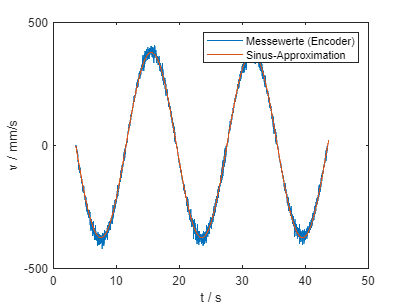


figure()
plot(t, vXEncGlobal, t, fncvXEncGlobal(t, bOptvXEncGlobal));
legend('Messewerte (Encoder)', 'Sinus-Approximation')
xlabel("t / s")
ylabel("v / mm/s")

## Sinus-Approximation der x-Position (Kamera)

fncXCam = @(x, b) (b(1)*sin(2*pi*b(2)*x + b(3)) + b(4))

fncXCam = function_handle with value:
    @(x,b)(b(1)*sin(2*pi*b(2)*x+b(3))+b(4))


fitXCam = @(b)(sum((fncXCam(t',b)-xCam').^2))

fitXCam = function_handle with value:
    @(b)(sum((fncXCam(t',b)-xCam').^2))


b0XCam = [980, 1/16, 0, 2.8380e+03];
bOptXCam = fminsearch(fitXCam, b0XCam)

bOptXCam = 	1.0e+03 *

    0.9616    0.0001    0.0001    2.8260


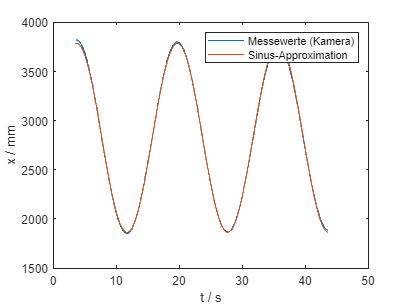


figure()
plot(t, xCam, t, fncXCam(t, bOptXCam));
legend('Messewerte (Kamera)', 'Sinus-Approximation')
xlabel("t / s")
ylabel("x / mm")

## Bestimmung des Kamera-Delays

% Phasendifferenz zwischen xCam und vXEncoder
bOptXCam(3)

ans = 0.1065

bOptvXEncGlobal(3)

ans = 1.7404

camDelayInRad = (bOptXCam(3) + pi/2) - bOptvXEncGlobal(3)

camDelayInRad = -0.0631


averageCycleTime = (1 / bOptXCam(2) + 1 / bOptvXEncGlobal(2)) / 2

averageCycleTime = 15.9950

camDelayInSeconds = camDelayInRad / (2*pi) * averageCycleTime

camDelayInSeconds = -0.1605

## Plots

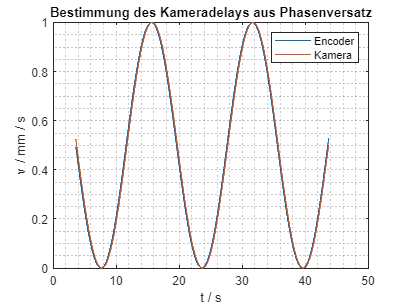

bOptXCamShifted = bOptXCam;
bOptXCamShifted(3) = bOptXCamShifted(3) + pi/2;
plot(t, rescale(fncvXEncGlobal(t, bOptvXEncGlobal)), t, rescale(fncXCam(t, bOptXCamShifted)));
legend('Encoder', 'Kamera');
title('Bestimmung des Kameradelays aus Phasenversatz')
xlabel(['t / s']), ylabel('v / mm / s')
grid minor